clear
clc
format long

## Diferencias finitas Lineal

[x, y] = diferenciasfinitas('p','q','r',1,2,9,1,2);

## Diferencias finitas No Lineal

clear

[X,Y,iter,incr]=diferenciasfinitas_nolineal('f','fy','fz',1,3,17,43/3,19,19,1e-8);

clear
f=@(x,y,z) z+2*(y-log(x)).^3-1./x;
fy=@(x,y,z) 6.*(y-log(x)).^2;
fz=@(x,y,z) 1 + 0.*x + 0.*y + 0.*z;
[X,Y,iter,incr] = diferenciasfinitas_nolineal_2da_condicion_derivada(f, fy,fz, 2, 3, 1 + log(2), 2/9, 10, 100, 1e-5)

  Columns 1 through 6

   1.500075277889359   1.504319786263243   1.511948716799985   1.522389595176981   1.535223342181021   1.550142386914671

  Columns 7 through 10

   1.566920540183067   1.585391108168834   1.605430880319235   1.626948386333342

  Columns 1 through 6

   1.671674187585816   1.658331477383519   1.651507460052434   1.650044277126714   1.653115081098697   1.660142480202199

  Columns 7 through 10

   1.670743898646128   1.684695157736712   1.701906892320271   1.722410462085988

  Columns 1 through 6

   1.668530402133190   1.653057680227383   1.644776729186387   1.642310904098114   1.644690093719871   1.651241984654983

  Columns 7 through 10

   1.661521183004318   1.675263058001266   1.692354494871266   1.712816915660564

  Columns 1 through 6

   1.668522262324596   1.653040682101391   1.644750662700409   1.642276065336071   1.644647181339700   1.651192001407980

  Columns 7 through 10

   1.661465367182661   1.675202844397714   1.692291498354930   1.7127529297697

X =    2.000000000000000   2.100000000000000   2.200000000000000   2.300000000000000   2.400000000000000   2.500000000000000   2.600000000000000   2.700000000000000   2.800000000000000   2.900000000000000   3.000000000000000


Y =    1.693147180559945   1.668522262116144   1.653040681655119   1.644750661985992   1.642276064330384   1.644647180033519   1.651191999810623   1.661465365324428   1.675202842330228   1.692291496149584   1.712752927514523


iter =      5


incr =      2.255265087321814e-09


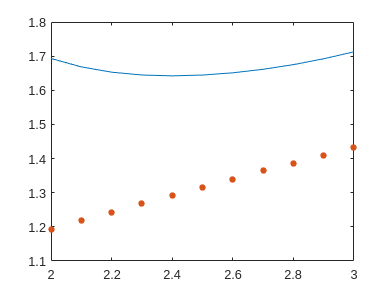

solex=X.^(-1) + log(X);

plot(X,Y)
hold on
plot(X, solex, '.', 'markersize', 15)
hold off